Import image and convert to gray scale,double. Record size of image.

clc;clear;
load('Contrast2.mat');
load('Contrast1.mat');
[m,n]=size(Contrast2);
origin=Contrast1;
translated=Contrast2;


Calculate myNCC

R_beforeregis=myNCC(origin(4:end,3:end),translated(4:end,3:end));
diff1=origin-translated;

In order to translate the contrast2 back. We should translate -1.8 in x and -2.1 in y.

dx=-1.8;
dy=-2.1;

Now translate in x and y direction and calculate pixel value using intepolation.(backward transformation)

% Create a grid of coordinates
[X, Y] = meshgrid(1:n, 1:m);

% Compute the translated coordinates
X_regis = X + dx;
Y_regis = Y + dy;

% Initialize the output image with NaNs
regis_image = NaN(m, n);

% Find the integer coordinates surrounding the translated coordinates
x1 = floor(X_regis);
x2 = ceil(X_regis);
y1 = floor(Y_regis);
y2 = ceil(Y_regis);

% Identify valid interpolation points (within image bounds)
validMask = x1 >= 1 & x2 <= n & y1 >= 1 & y2 <= m;

% Interpolation weights
wx = X_regis - x1;
wy = Y_regis - y1;

% Retrieve pixel values at the four surrounding points for valid points
Q11 = NaN(m, n); Q21 = NaN(m, n);
Q12 = NaN(m, n); Q22 = NaN(m, n);

Q11(validMask) = double(translated(sub2ind([m, n], y1(validMask), x1(validMask))));
Q21(validMask) = double(translated(sub2ind([m, n], y1(validMask), x2(validMask))));
Q12(validMask) = double(translated(sub2ind([m, n], y2(validMask), x1(validMask))));
Q22(validMask) = double(translated(sub2ind([m, n], y2(validMask), x2(validMask))));

% Perform bilinear interpolation for valid points
regis_image(validMask) = (1 - wx(validMask)) .* (1 - wy(validMask)) .* Q11(validMask) + ...
    wx(validMask) .* (1 - wy(validMask)) .* Q21(validMask) + ...
    (1 - wx(validMask)) .* wy(validMask) .* Q12(validMask) + ...
    wx(validMask) .* wy(validMask) .* Q22(validMask);
regis_image(isnan(regis_image)) = 0;

Calculate myNCC and subtract image with Contrast1

Difference=origin-regis_image;
% regis_image=uint8(regis_image);
% origin=uint8(origin);
% translated=uint8(translated);
R_afterregistration=myNCC(origin(4:end,3:end),regis_image(4:end,3:end));

 Print the result value and show the difference image with scale bar

fprintf('The result before registration is %d and after registration is %d.\n',R_beforeregis,R_afterregistration);

The result before registration is 9.778922e-01 and after registration is 9.998184e-01.


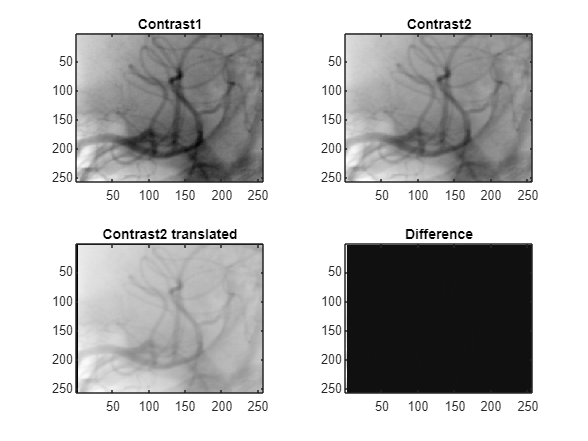


tiledlayout(2,2)
nexttile
imagesc(origin)
colormap('gray')
title('Contrast1')

nexttile
imagesc(translated)
title('Contrast2')
colormap('gray')
nexttile
imagesc(regis_image)
title('Contrast2 translated')
colormap('gray')
nexttile
imagesc(Difference)
title('Difference')
colormap('gray')

Q3

NEW

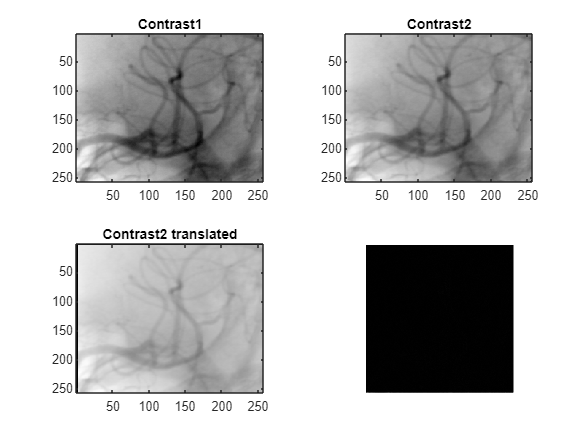

%initialize first guess for translation, [tx, ty]
t_i= [0,0];
frames = struct('cdata', {}, 'colormap', {});
%initialize array
param=struct();
param.scaling=1;

%calling the cost function SSE
costF= @(t) registrationcost(t, origin, translated);
%costF= @(t) SSE(origin, translated, t(1),t(2), param );
% cost_test= SSE(origin, translated, -1.8, -2.1);
% display(cost_test)

%run fminsearch on optimal translation parameters
% and custom options to show iterations
options = optimset( 'TolFun',1e-3, 'TolX',1e-3);
%     'OutputFcn', @(x, optimValues, state) ...
%     updateFrames(x, optimValues, state, frames) 
                    %'OutputFcn',@regOutFun);
[t_optimal, fval]= fminsearch(costF, t_i, options);


fprintf(['The optimal translation parameters t_x is %.4f, t_y is %4f, ' ...
    'and minimal cost function is %d\n'], ...
    t_optimal(1), t_optimal(2), fval);

The optimal translation parameters t_x is 1.8398, t_y is 2.064162, and minimal cost function is 7.100666e+04


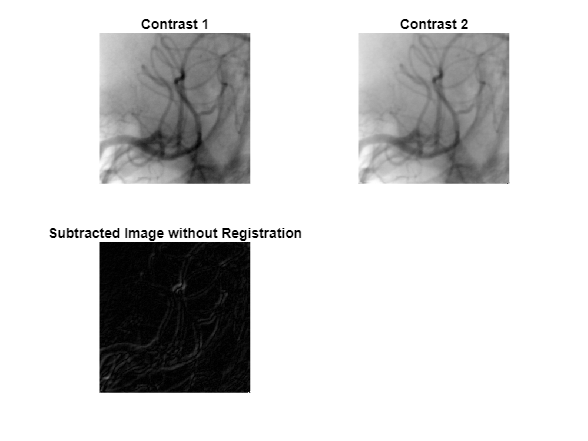


%subtracted image without registration
diffImg_noReg= abs(origin-translated);

figure;
subplot(2,2,1), imshow(origin,[]), title('Contrast 1');
subplot(2,2,2), imshow(translated,[]), title('Contrast 2');
subplot(2,2,3), imshow(uint8(diffImg_noReg)), title('Subtracted Image without Registration');


figure;
axis off;

movie(frames);


function cost = registrationcost(params, fixedImage, movingImage)
    persistent frames;
    if isempty(frames)
        frames = struct('cdata', {}, 'colormap', {});
    end

    % Extract translation parameters
    tx = params(1);
    ty = params(2);

    % Translate the moving image
    translatedImage = imtranslate(movingImage, [tx, ty]);

    % Compute the difference image
    differenceImage = abs(fixedImage - translatedImage);

    % Compute the sum of squared errors
    cost = sum(differenceImage(4:end,3:end).^2,"all");

    % Capture the difference image as a frame
    figure(100);
    imshow(uint8(differenceImage));
    drawnow;
    frame = getframe(gcf);
    
    % Store the frame
    frames(end+1) = frame;

    % Assign the updated frames to the base workspace
    assignin('base', 'frames', frames);
end
%%


Q4

t_i= [0,0];
%initialize array
param=struct();
param.scaling=1;

tolFun = [1e-1, 1e-3, 1e-5]; % Different TolFun values
tolX = [1e-1, 1e-3, 1e-5];   % Different TolX values
scaling= [1,10,100] % scaling factor

scaling =      1    10   100



costF= @(t) SSE(origin, translated, t(1),t(2),param );

%initialize arrays to store result
results_fun=[];
results_x=[];
results_scaling=[];
%chaing tolerance for function value
for f=1:length(tolFun)
    options=optimset('TolFun', tolFun(f),'Display','off');
    [t_op, fvalue,exitflag, output]=fminsearch(costF, t_i, options)
    r1.TolFun= tolFun(f);
    r1.Cost= fvalue;
    r1.Iteration= output.iterations;
    if exitflag==1;
        r1.Outcomes='Sucess';
    else
        r1.Outcomes='Failure';
    end
    results_fun= [results_fun, r1];
end

t_op =     0.0193    0.0309


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 42
     funcCount: 82
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 ↵'


t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 51
     funcCount: 99
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-03 ↵'


t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 58
     funcCount: 112
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-05 ↵'


table1= struct2table(results_fun);
disp(table1);

    TolFun       Cost       Iteration     Outcomes 
    ______    __________    _________    __________

      0.1     9.0673e+06       42        {'Sucess'}
    0.001     9.0673e+06       51        {'Sucess'}
    1e-05     9.0673e+06       58        {'Sucess'}



%changing tolerance for x value
for x= 1:length(tolX)
    options= optimset('TolX', tolX(x),'Display','off');
    [t_op, fvalue,exitflag, output]=fminsearch(costF, t_i, options)
    r2.TolX= tolX(x);
    r2.Cost=fvalue;
    r2.Iteration= output.iterations;
    if exitflag==1;
        r2.Outcomes='Sucess';
    else
        r2.Outcomes='Failure';
    end
    results_x=[results_x, r2];
end

t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-03 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-05 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


table2= struct2table(results_x);
disp(table2);

    TolX        Cost       Iteration     Outcomes 
    _____    __________    _________    __________

      0.1    9.0673e+06       54        {'Sucess'}
    0.001    9.0673e+06       54        {'Sucess'}
    1e-05    9.0673e+06       54        {'Sucess'}




%changing scaling factor
for s=1:length(scaling)
    param.scaling= scaling(s);
    options=optimset('Display','off');
    [t_op, fvalue,exitflag, output]=fminsearch(costF, t_i, options)
    r3.Scale= scaling(s);
    r3.Cost=fvalue;
    r3.Iteration= output.iterations;
    if exitflag==1;
        r3.Outcomes='Sucess';
    else
        r3.Outcomes='Failure';
    end
    results_scaling=[results_scaling, r3];
end

t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


t_op =     0.0192    0.0308


fvalue = 9.0673e+06

exitflag = 1

output = struct with fields:
    iterations: 54
     funcCount: 105
     algorithm: 'Nelder-Mead simplex direct search'
       message: 'Optimization terminated:↵ the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-04 ↵ and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-04 ↵'


table3= struct2table(results_scaling);
disp(table3);

    Scale       Cost       Iteration     Outcomes 
    _____    __________    _________    __________

       1     9.0673e+06       54        {'Sucess'}
      10     9.0673e+06       54        {'Sucess'}
     100     9.0673e+06       54        {'Sucess'}

